# NPCC 140-bus model analysis

## Load the data

npccFile = "D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NPCC140\npcc.xlsx";
npccBus = importNpccBus(npccFile);
npccPV = importNpccPV(npccFile);
npccPQ = importNpccPQ(npccFile);
npccSlack = importNpccSlack(npccFile);
npccLine = importNpccLine(npccFile);

## Bus data analysis

There are 2 buses with 2 generators and 9 buses with 2 loads.

busGenSum = groupsummary(npccPV, "bus", "sum", ["p0","q0"]);
busGenSum.Properties.VariableNames = ["bus","numGen","sumGenP0","sumGenQ0"];
busMultiGen = busGenSum(busGenSum.numGen > 1, :)

busMultiGen = 2×4 table
    bus    numGen    sumGenP0    sumGenQ0
    ___    ______    ________    ________

    23       2         5.03       0.19615
    54       2        11.15      -0.01298


busLoadSum = groupsummary(npccPQ, "bus", "sum", ["p0","q0"]);
busLoadSum.Properties.VariableNames = ["bus","numLoad","sumLoadP0","sumLoadQ0"];
busMultiLoad = busLoadSum(busLoadSum.numLoad > 1, :)

busMultiLoad = 9×4 table
    bus    numLoad    sumLoadP0    sumLoadQ0
    ___    _______    _________    _________

    46        2         0.23        -0.425  
    95        2           -1          0.87  
    96        2         -0.4         -0.25  
    124       2          3.7          0.49  
    127       2            2          -1.5  
    128       2          9.7         -1.02  
    129       2          6.1          -0.5  
    131       2         11.6         -4.32  
    132       2          2.1         -3.37  


npccBusJoint = outerjoin(npccBus, busGenSum, "LeftKeys","idx","RightKeys","bus","MergeKeys",true,"Type","left");
npccBusJoint = outerjoin(npccBusJoint, busLoadSum, "LeftKeys","idx_bus","RightKeys","bus","MergeKeys",true,"Type","left");
npccBusJoint.Properties.VariableNames(1) = "busIdx";
npccBusJoint.busType(~ismissing(npccBusJoint.numGen)) = 2; % PV bus
npccBusJoint.busType(ismissing(npccBusJoint.numGen)) = 1; % PQ bus
slackBusIdx = npccSlack.bus(1);
npccBusJoint.busType(npccBusJoint.busIdx == slackBusIdx) = 3; % Slack bus
npccBusJoint.busType = categorical(npccBusJoint.busType);
npccBusJoint = movevars(npccBusJoint,"busType","After","busIdx");
% Fill missing data
npccBusJoint.numGen = fillmissing(npccBusJoint.numGen, "constant", 0);
npccBusJoint.sumGenP0 = fillmissing(npccBusJoint.sumGenP0, "constant", 0);
npccBusJoint.sumGenQ0 = fillmissing(npccBusJoint.sumGenQ0, "constant", 0);
npccBusJoint.numLoad = fillmissing(npccBusJoint.numLoad, "constant", 0);
npccBusJoint.sumLoadP0 = fillmissing(npccBusJoint.sumLoadP0, "constant", 0);
npccBusJoint.sumLoadQ0 = fillmissing(npccBusJoint.sumLoadP0, "constant", 0);
% Add Slack bus p0, q0 to sumGenP0 and sumGenQ0
npccBusJoint.sumGenP0(npccBusJoint.busType == "3") = npccSlack.p0(1);
npccBusJoint.sumGenQ0(npccBusJoint.busType == "3") = npccSlack.q0(1);

busTypeSummary = groupsummary(npccBusJoint, "busType")

busTypeSummary = 3×2 table
    busType    GroupCount
    _______    __________

       1           94    
       2           45    
       3            1    


pqBus = npccBusJoint(npccBusJoint.busType == "1", :);
pvBus = npccBusJoint(npccBusJoint.busType == "2", :);
slackBus = npccBusJoint(npccBusJoint.busType == "3", :);

npccBusJoint

npccBusJoint = 140×20 table
    busIdx    busType    u        name        Vn     vmax    vmin      v0         a0       xcoord    ycoord     area    zone    owner    numGen    sumGenP0    sumGenQ0    numLoad    sumLoadP0    sumLoadQ0
    ______    _______    _    ____________    ___    ____    ____    ______    ________    ______    _______    ____    ____    _____    ______    ________

### Compare the data with MatPower case file

It agrees well.

load("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NPCC140\Code\npcc.mat");
mpcBus = array2table(mpc.bus);
mpcBus.Properties.VariableNames = ["BUS_I","BUS_TYPE","PD","QD","GS","BS","BUS_AREA","VM","VA","BASE_KV","ZONE","VMAX","VMIN"];
mpcBus

mpcBus = 140×13 table
    BUS_I    BUS_TYPE    PD     QD     GS    BS    BUS_AREA      VM        VA      BASE_KV    ZONE    VMAX    VMIN
    _____    ________    ___    ___    __    __    ________    ______    ______    _______    ____    ____    ____

      1         1          0      0    0     0        1        1.0152    4.8434      345       1      1.1     0.9 
      2         1          0      0    0     0        1        1.0109    4.0566      345       1      1.1     0.9 
      3         1          9     88    0     0        1        0.9917    4.

mpcBusTypeSummary = groupsummary(mpcBus, "BUS_TYPE")

mpcBusTypeSummary = 3×2 table
    BUS_TYPE    GroupCount
    ________    __________

       1            94    
       2            45    
       3             1    


### Geographic plot of npcc 140 buses

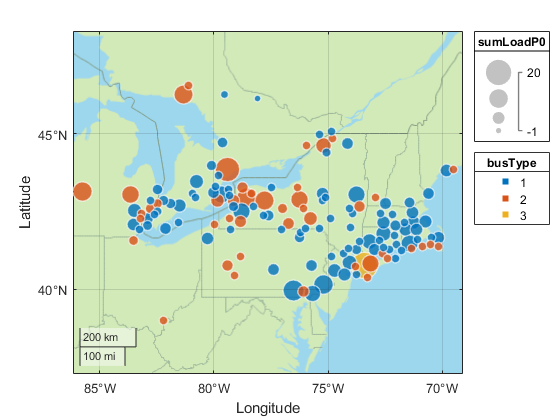

figure;
geobubble(npccBusJoint,"xcoord","ycoord","SizeVariable","sumLoadP0","ColorVariable","busType","Basemap","bluegreen");

## Transmission line analysis

npccLine

npccLine = 233×20 table
      idx      u      name       bus1    bus2    Sn     fn    Vn1    Vn2      r         x        b      g    b1    g1    b2    g2    trans    tap    phi
    _______    _    _________    ____    ____    ___    __    ___    ___    ______    ______    ____    _    __    __    __    __    _____    ___    ___

npccLineJoint = outerjoin(npccLine,npccBus,"Type","left","LeftKeys","bus1","RightKeys","idx","MergeKeys",true,"RightVariables",["name","area","xcoord","ycoord","zone"]);
npccLineJoint.Properties.VariableNames(end-4:end) = ["bus1_name","bus1_area","bus1_xcoord","bus1_ycoord","bus1_zone"];
npccLineJoint = outerjoin(npccLineJoint,npccBus,"Type","left","LeftKeys","bus2","RightKeys","idx","MergeKeys",true,"RightVariables",["name","area","xcoord","ycoord","zone"]);
npccLineJoint.Properties.VariableNames(end-4:end) = ["bus2_name","bus2_area","bus2_xcoord","bus2_ycoord","bus2_zone"];
npccLineJoint

npccLineJoint = 233×30 table
      idx       u    name_npccLine    bus1_idx    bus2_idx    Sn     fn    Vn1    Vn2      r         x        b      g    b1    g1    b2    g2    trans    tap    phi     bus1_name      bus1_area    bus1_xcoord    bus1_ycoord    bus1_zone     bus2_name      bus2_area    bus2_xcoord    bus2_ycoord    bus2_zone
    ________    _    _____________    ________    ________    

edges = [0, 100, 200, 300, 400, 1000];
npccLineJoint.voltageClass = discretize(max(npccLineJoint.Vn1,npccLineJoint.Vn1),edges,"categorical",{'<100','100-200','220/230','345','500'})

npccLineJoint = 233×31 table
      idx       u    name_npccLine    bus1_idx    bus2_idx    Sn     fn    Vn1    Vn2      r         x        b      g    b1    g1    b2    g2    trans    tap    phi     bus1_name      bus1_area    bus1_xcoord    bus1_ycoord    bus1_zone     bus2_name      bus2_area    bus2_xcoord    bus2_ycoord    bus2_zone    voltageClass
    ________    _    _____________    ________    

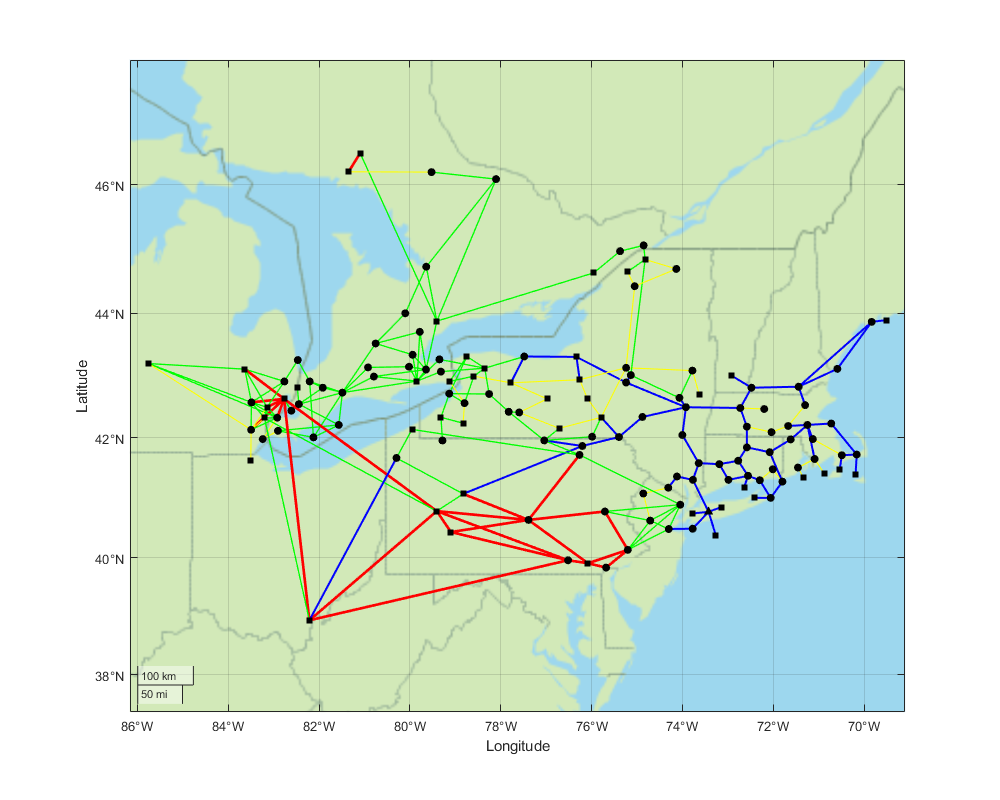

numLine = height(npccLineJoint);
figure;
gx = geoaxes;
hold on;
for i=1:numLine
    lat1 = npccLineJoint.bus1_xcoord(i);
    lon1 = npccLineJoint.bus1_ycoord(i);
    lat2 = npccLineJoint.bus2_xcoord(i);
    lon2 = npccLineJoint.bus2_ycoord(i);
    if npccLineJoint.voltageClass(i) == "500"
        lineSpec = "r-"; lineWidth = 2;
    elseif npccLineJoint.voltageClass(i) == "345"
        lineSpec = 'b-'; lineWidth = 1.5;
    elseif npccLineJoint.voltageClass(i) == "220/230"
        lineSpec = 'g-'; lineWidth = 1;
    else
        lineSpec = 'y-'; lineWidth = 0.8;
    end
    geoplot(gx, [lat1, lat2], [lon1, lon2],lineSpec,"LineWidth",lineWidth);
end
geoscatter(pvBus.xcoord, pvBus.ycoord, "filled", 'ks');
geoscatter(slackBus.xcoord, slackBus.ycoord, "filled", 'k^');
geoscatter(pqBus.xcoord, pqBus.ycoord, "filled", 'ko');
hold off;
gx.Basemap = "bluegreen";
set(gcf, "Position", [100,100,1000,800]);

## Load generator data